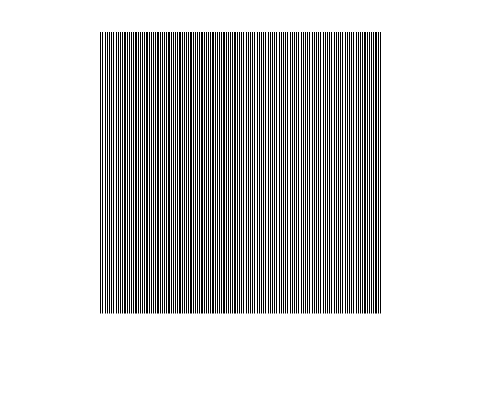

r = 256;
c = 256;
vStripes = ones(r,c)*255;
for i = 1:(r/2)
    for j = 1:c
        vStripes(j, 2*i) = 0;
    end
end
imshow(vStripes);

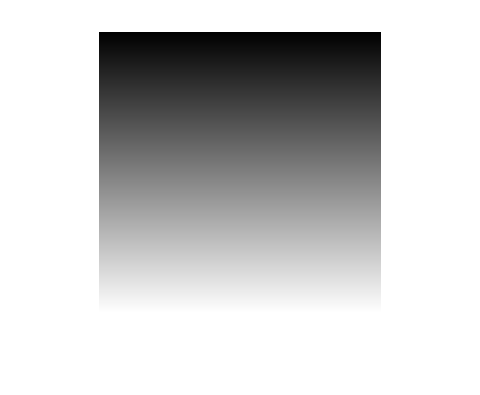

hStripes = transpose(vStripes);

generateFile(vStripes, 'vStripes');
generateFile(hStripes, 'hStripes');


vShade = zeros(r,c,'uint8');
for i = 1:r
    for j = 1:c
        vShade(i,j) = i-1;
    end
end
imshow(vShade);

hShade = transpose(vShade);
generateFile(vShade, 'vShade');
generateFile(hShade, 'hShade');

noise = randi([0, 255], r, c, 'uint8');
generateFile(noise, 'noise');

Applicando la predizione lineare semplice del punto 5 si ottengono i seguenti risultati

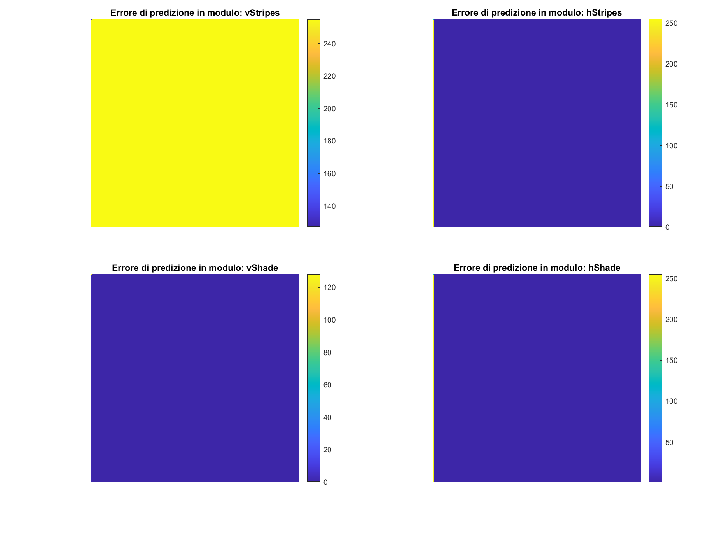

figure; tiledlayout(2,2,"TileSpacing", 'None', "Padding", 'none');
nexttile; imshow(vStripesPredErr); nexttile; imshow(hStripesPredErr);
nexttile; imshow(vShadePredErr  ); nexttile; imshow(hShadePredErr  );

## Utilities

function generateFile(matrix, name)
    [row, col] = size(matrix);
    filename = sprintf('%s.pgm',name);
    imwrite(matrix, filename);
end